# Distribution of N Choose N/2-x

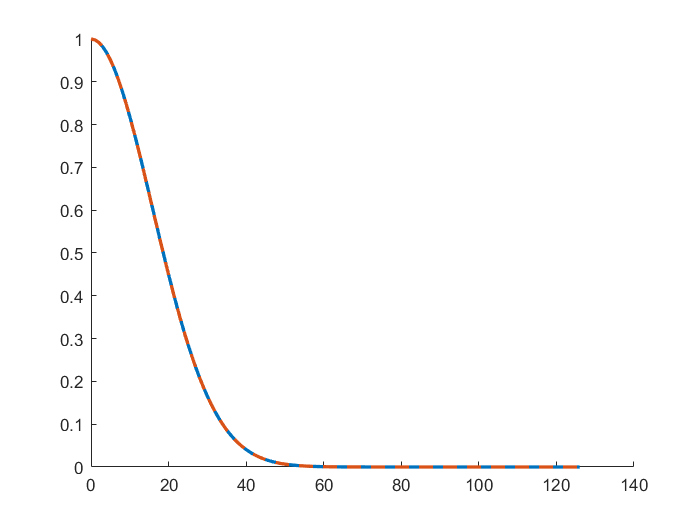

warning off
N = 1000;
N_choose_halfN = nchoosek(N,N/2);
xRange = 0:4*sqrt(N);

N_choose_halfNminusx = zeros(1,length(xRange));
for ii =1:length(xRange)
    N_choose_halfNminusx(ii) = nchoosek(N,N/2-xRange(ii));
end

figure
hold on
plot(xRange,N_choose_halfNminusx/N_choose_halfN,'LineWidth',2)
plot(xRange,exp(-2*power(xRange,2)/N),'LineStyle',"--",'LineWidth',2)

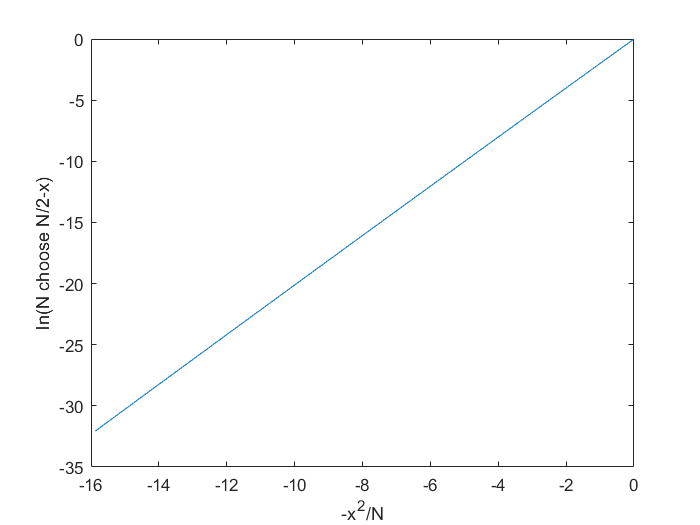


figure
plot(-power(xRange,2)/N,log(N_choose_halfNminusx/N_choose_halfN))
xlabel('-x^2/N')
ylabel('ln(N choose N/2-x)')

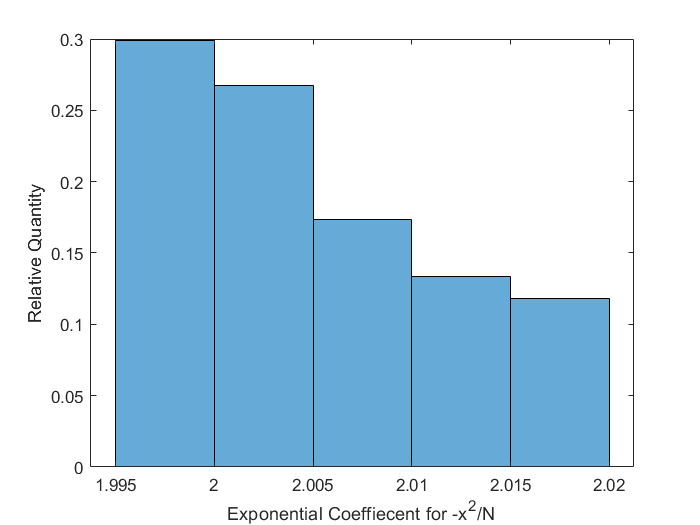


histogram(log(N_choose_halfNminusx/N_choose_halfN)./(-power(xRange,2)/N),'Normalization',"probability")
xlabel('Exponential Coeffiecent for -x^2/N')
ylabel('Relative Quantity')

warning on